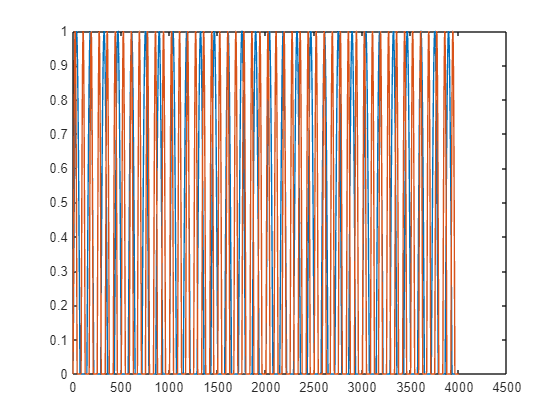

user=5;
inter=2;
if user<10
    fname=strcat('a0', num2str(user));
    name=strcat('a0', num2str(user),'.fqrs.txt');
else

    fname=strcat('a', num2str(user));
    name=strcat('a', num2str(user),'.fqrs.txt');
end

[signal fs]= rdsamp(fname,[], []);

ann=rdann(fname,'fqrs',[],[]);
ann=floor(ann/5);
ECG=signal;
tm=0.001:0.001:60;
tm=tm';
cName=fname;
% qrsAf=ann;
qrsAf=[];

dbFlag=0;                   % debug flag
graph=0;                    % enable/disable graphical representation
saveFig=0;                  % =1 => save figures of the processing phases
saveFigRRf=0;               % =1 => save estimated fetal RR figures




fs=200;
t=0:1/fs:20;
x1=sin(2*pi*7*t/5);
x2=sin(2*pi*12*t/5);
x3=sin(2*pi*12*t/5);
b=find(x1<0);
x1(b)=0;
b=find(x3<0);
x3(b)=0;
x2(find(x2<0))=0;
plot(x1);
hold on;
plot(x3);

x=x1+x3;
X=[x1+x3;0.33*x1+2*x3;0.7*x1-2.99*x3]

X =          0    0.1193    0.2381    0.3558    0.4721    0.5863    0.6980    0.8067    0.9119    1.0133    1.1103    1.2027    1.2899    1.3717    1.4478    1.5177    1.5814    1.6385    1.6888    1.7322    1.7685    1.7977    1.8197    1.8344    1.8418    1.8421    1.8352    1.8213    1.8005    1.7731    1.7391    1.6989    1.6527    1.6008    1.5436    1.4813    1.4143    1.3430    1.2679    1.1893    1.1076    1.0233    0.9620    0.9491    0.9343    0.9178    0.8994    0.8793    0.8575    0.8341
         0    0.1652    0.3294    0.4920    0.6518    0.8082    0.9603    1.1072    1.2483    1.3826    1.5096    1.6285    1.7388    1.8398    1.9310    2.0119    2.0822    2.1414    2.1893    2.2257    2.2503    2.2631    2.2640    2.2531    2.2304    2.1961    2.1505    2.0937    2.0262    1.9484    1.8607    1.7635    1.6576    1.5435    1.4219    1.2933    1.1587    1.0188    0.8742    0.7260    0.5748    0.4216    0.3175    0.3132    0.3083    0.3029    0.2968    0.2902    0.2830    0

X=X';
% plot(x)
y=FecgICAm(X,fs,cName,0,dbFlag,saveFig);


 --------------------------------------------------------- 
Program: FecgICAm,  record name: a05
FastIca, cosh , deflationary 
epsilon=    0.000100 
Component=  1
w1:0.450129
w1:-0.268861
w1:0.106843
numIt=201, 0.100520
  ==> Convergence failure!
Component=  2
w1:-0.014018
w1:0.391299
w1:0.262097
numIt= 10, 0.000091
  ==> Convergence failure!
Component=  3
w1:-0.043532
w1:-0.481496
w1:0.321407
numIt=  3, 0.000000
  ==> Convergence failure!
FastIca, kurt , deflationary 
epsilon=    0.000100 
Component=  1
numIt= 10, 0.000094
Component=  2
numIt=  5, 0.000021
Component=  3
numIt=  3, 0.000000
